# Kameramessrauschen ermitteln

Dieses Skript dient der Ermittlung des Messrauschens des Kamerasystems.

Hierzu wurden von den Roboter 2, 3 und 4 jeweils die Kamerapositionen im Stillstand aufgezeichnet.

## Einlesen des Datensatzes

% Zu importierende Datei auswählen
filename = "CameraNoise_Long";

% Importieren und nicht relevante Informationen entfernen
data = readtable(filename);
data([1:230],:)=[];




% Generiere array aus tbale fuer pose2. Enthaelt Pose fuer Roboter 2 usw.
pose2 = table2array([data(:,"cam2x"), data(:,"cam2y"), data(:,"cam2theta")]);
pose3 = table2array([data(:,"cam3x"), data(:,"cam3y"), data(:,"cam3theta")]);
pose4 = table2array([data(:,"cam4x"), data(:,"cam4y"), data(:,"cam4theta")]);

% Bereinigen der einzelnen Datensaetze (Nullen von Kamera werden gesendet,
% wenn Fehler bei Positionsberehcnung. NaN werden ebenso entfernt. Nullen
% koennen entfernt werden, da bei Beobachter-Berechnungen diese
% unplausiblen Werte ebenso nicht im Korrekturschritt genutzt werden. Somit
% stellt dies keine Verzerrung der Statistik dar.
pose2(pose2 == 0) = NaN;
pose2(any(isnan(pose2), 2), :) = [];    %isnan() erzeugt logischen Vektor, je nach dem ob NaN in entsprechender. any(bool,2) geht Zeileweise durch (dafuer die 2 (2dimensionales Arry)) und erzeugt true, wenn logical 1 or non-zero in der Zeile

pose3(pose3 == 0) = NaN;
pose3(any(isnan(pose3), 2), :) = [];

pose4(pose4 == 0) = NaN;
pose4(any(isnan(pose4), 2), :) = [];




x2 = pose2(:,1);
y2 = pose2(:,2);
theta2 = pose2(:,3);

%% Mittelwert befreien, da Gauß Annahmne Kalman mittlwertfreies Rauschen
x2 = x2 - mean(x2);
y2 = y2 - mean(y2);
theta2 = theta2 - mean(theta2);

% calculate Normal distribution of x2
pdx2=fitdist(x2,'Normal')

pdx2 =   NormalDistribution

  Normal distribution
       mu = -3.57277e-14   [-0.000392581, 0.000392581]
    sigma =     0.024168   [0.0238936, 0.0244488]


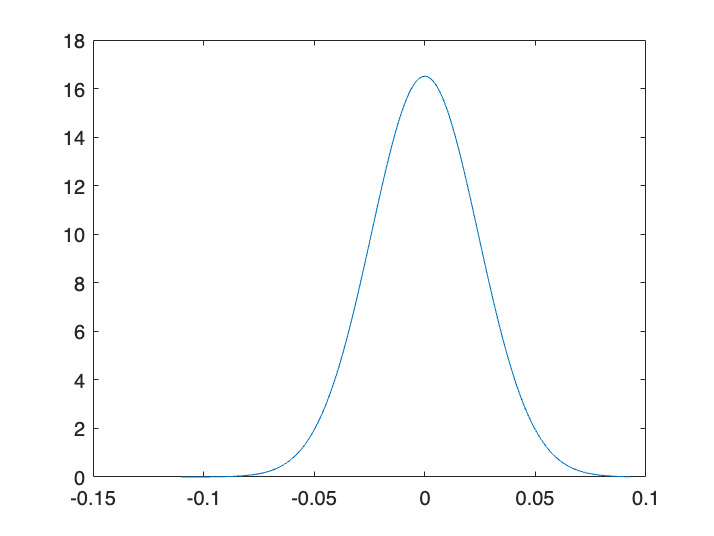

x_values = min(x2):1e-3:max(x2);
y = pdf(pdx2,x_values);
plot(x_values,y)


% "haendische" Varianzberechnung (optional)
sumx=0;
for i = 1:length(x2)
    sumx = sumx + x2(i)^2;
end
varx = 1/(length(x2)-1)*sumx

varx = 5.8409e-04


% calculate Normal distribution of y2
pdy2=fitdist(y2,'Normal')

pdy2 =   NormalDistribution

  Normal distribution
       mu = -5.17802e-14   [-0.000234726, 0.000234726]
    sigma =    0.0144501   [0.0142861, 0.0146181]


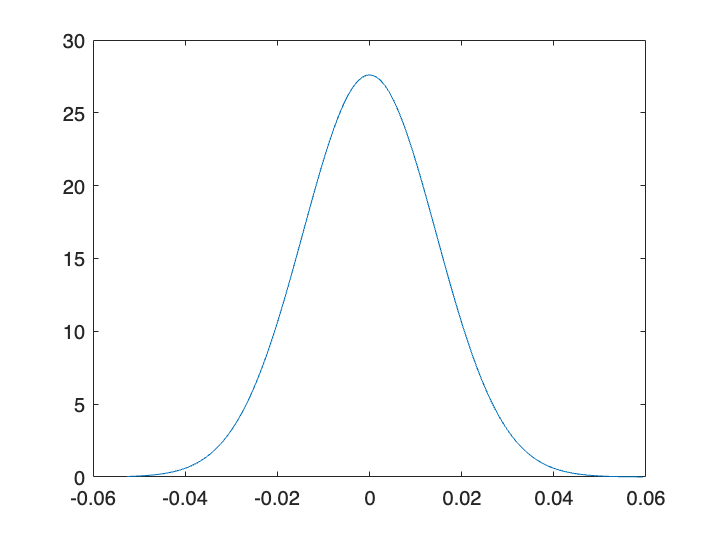

x_values = min(y2):1e-3:max(y2);
y = pdf(pdy2,x_values);
plot(x_values,y)


% calculate Normal distribution of theta2
pdt2=fitdist(theta2,'Normal')

pdt2 =   NormalDistribution

  Normal distribution
       mu = -1.33927e-17   [-3.91732e-06, 3.91732e-06]
    sigma =  0.000241157   [0.000238419, 0.000243959]


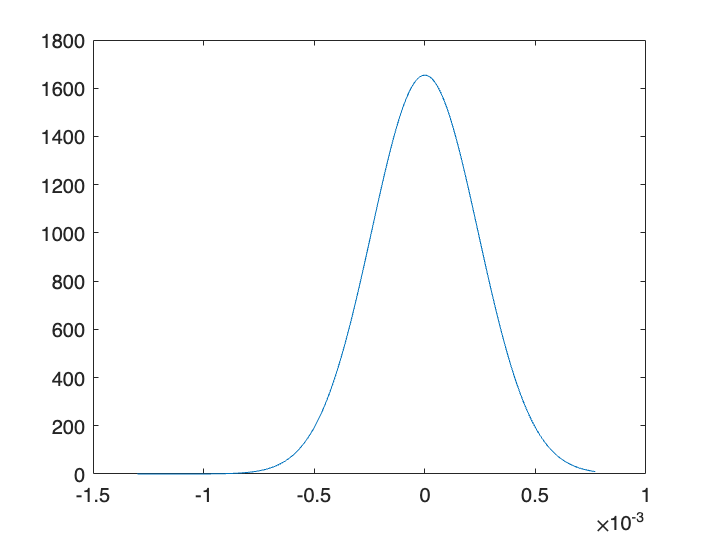

x_values = min(theta2):1e-5:max(theta2);
y = pdf(pdt2,x_values);
plot(x_values,y)


% Varianz fuer Roboter 3 in x,y und theta


## Kurzloesung

cov2 = cov(pose2)

cov2 = 1.0e-03 *

    0.5841    0.1135    0.0036
    0.1135    0.2088    0.0014
    0.0036    0.0014    0.0001


cov3 = cov(pose3)

cov3 =     0.0011   -0.0003    0.0000
   -0.0003    0.0014   -0.0000
    0.0000   -0.0000    0.0000


cov4 = cov(pose4)

cov4 =     0.0013   -0.0014    0.0000
   -0.0014    0.0143   -0.0000
    0.0000   -0.0000    0.0000
